# Experimental Methods HW #5 Dan Lawson

## Problem 1: Hot Wire Calibration

% Using Polyfit, fit the following data with a third order polynomial
% Fit with a 90% confidence 
clear

E = [9.52 5.22 3.76 2.81 2.06];
U = [0 8.38 17.27 26.08 34.83];
X = linspace(2,10,1e3);

p3 = polyfit(E, U, 3);
U_fit3 = polyval(p3, X);
U_cfit3 = polyval(p3, E);
 
sig_U3 = sqrt(sum((U - U_cfit3).^2)/(length(E)-4));
err3 = t_value(0.9, length(U)-4)*sig_U3

err3 = 0.4395


figure;

plot(E, U, 'ko', 'DisplayName', 'Original Data');
hold on;
plot(X, U_fit3, 'b-', 'DisplayName', '3rd Order Fit');

% Now, fit with a fourth order polynomial
% Fit with a 90% confidence

p4 = polyfit(E, U, 4);
U_fit4 = polyval(p4, X);
U_cfit4 = polyval(p4, E);

sig_U4 = sqrt(sum((U - U_cfit4).^2)/(length(E)-5));
err4 = t_value(0.9, length(U)-4)*sig_U4

err4 = Inf

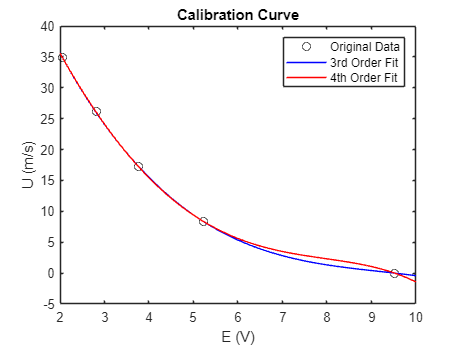


plot(X, U_fit4, 'r-', 'DisplayName', '4th Order Fit');

ylabel('U (m/s)');
xlabel('E (V)');
title('Calibration Curve');
legend('show','Location','northeast');
hold off;

% Repeat the previous fits with additional calibration points
clear

U = [0 4.06 8.38 12.82 17.27 21.68 26.08 30.48 34.83];
E = [9.52 6.45 5.22 4.39 3.76 3.24 2.81 2.40 2.06];
X = linspace(2,10,1e3);

p3 = polyfit(E, U, 3);
U_fit3 = polyval(p3, X);
U_cfit3 = polyval(p3, E);
 
sig_U3 = sqrt(sum((U - U_cfit3).^2)/(length(E)-4));
err3 = t_value(0.9, length(U)-4)*sig_U3

err3 = 0.1329


figure;

plot(E, U, 'ko', 'DisplayName', 'Original Data');
hold on;
plot(X, U_fit3, 'b-', 'DisplayName', '3rd Order Fit');

% Now, fit with a fourth order polynomial
% Fit with a 90% confidence

p4 = polyfit(E, U, 4);
U_fit4 = polyval(p4, X);
U_cfit4 = polyval(p4, E);

sig_U4 = sqrt(sum((U - U_cfit4).^2)/(length(E)-5));
err4 = t_value(0.9, length(U)-5)*sig_U4

err4 = 0.1569

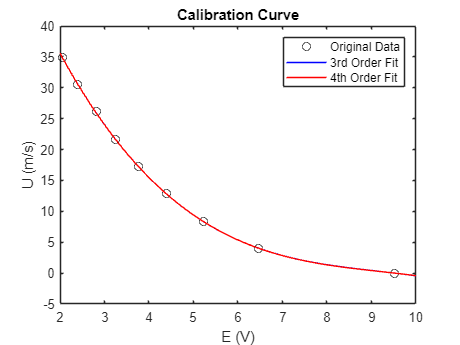


plot(X, U_fit4, 'r-', 'DisplayName', '4th Order Fit');

ylabel('U (m/s)');
xlabel('E (V)');
title('Calibration Curve');
legend('show','Location','northeast');
hold off;

## Problem 4: Amplitude Response

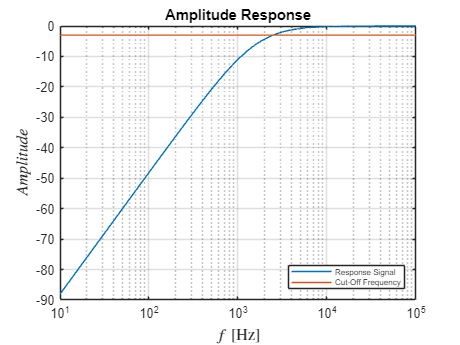

% For R = 10 ohms and C = 10 microF,  plot amplitude responses (in dB) as a
% function of f (in Hz), using 'semilogx' function for f = [10:10:100] kHz

    f = linspace(10, 100000, 10000);
    R = 10;
    C = 10e-6;
    w = zeros(size(f));
    A = zeros(size(f));
    
    for i = 1:length(f)
        w(i) = f(i) * 2 * pi;
        A(i) = 20 * log10(1 / sqrt((1 - (1 / (C * R * w(i)))^2)^2 + (2 / (C * R * w(i)))^2));
    end
    
    figure;
    semilogx(f, A,"DisplayName", 'Response Signal');
    hold on;
    hline = refline(0, 20 * log10(1 / sqrt(2)));
    set(hline, "DisplayName", 'Cut-Off Frequency');
    
    title('Amplitude Response')
    xlabel('$f$ [Hz]', 'Interpreter', 'latex', 'FontSize', 12);
    ylabel('$Amplitude$', 'Interpreter', 'latex', 'FontSize', 12);
    legend('Location', 'southeast', 'fontsize', 6);
    grid on;
    xlim([10, 100e3]);


    f_in = 1e3;
    amp = 5;
    w_in = f_in * 2 * pi

w_in = 6.2832e+03

    A_f = 1 / sqrt((1 - (1 / (C * R * w_in))^2)^2 + (2 / (C * R * w_in))^2)

A_f = 0.2830


    amp_out = amp * A_f

amp_out = 1.4152